clear; clc; close all;
in2m = 0.0254;
ft2m = 0.3048;
%% 1. Mission requirements
D_main_nmi = 5500;       % Main cruise air distance [nmi]
Mach_cruise = 0.82;      % Main cruise Mach number
h_cruise_ft = 37000;     % Main cruise altitude [ft]
h_cruise_ft2 = 20000;    % alternative airport cruise altitude [ft]
D_alternate_km = 370;    % Alternate distance [km]
h_loiter_ft = 5000;      % Loiter altitude [ft]
t_loiter_min = 45;       % Loiter duration [min]
M_alt = 0.6;
%% 2. Preliminary assumptions (editable)
% Taxi and takeoff
t_taxi_takeoff = 15;     % [min] given by book ref page 271

% Climb and accelerate to cruise
t_climb = 25;            % [min]

% Descent and approach to first destination
t_descent_1 = 25;        % [min]

% Missed approach, then climb and accelerate
t_climb_alternate = 25;  % [min]

% Average speed during short alternate leg
% Assumption: average TAS in knots, including speed variation
[T_alt, a_alt, P_alt, rho_alt] = atmosisa((h_cruise_ft2)*ft2m);
V_alternate_kts = a_alt*M_alt/0.51444444;   % [kt]

% Final descent and landing approach
t_descent_2 = 20;        % [min]
t_landing = 10;          % [min]

% Landing and taxi after touchdown
t_landing_taxi = 10;     % [min]

%% 3. Calculate cruise speed at 42,000 ft using ISA
% Approximate ISA temperature in the lower stratosphere
T_cruise_K = 216.65;     % [K]
gamma = 1.4;
R_air = 287.05;          % [J/(kg K)]
[T_cruise, a_cruise, P_cruise, rho_cruise] = atmosisa((37000)*ft2m);

V_cruise_kts= Mach_cruise * a_cruise/0.51444444;

fprintf('Cruise Mach number        = %.2f\n', Mach_cruise);

Cruise Mach number        = 0.82


fprintf('Cruise altitude            = %.0f ft\n', h_cruise_ft);

Cruise altitude            = 37000 ft


fprintf('Approx. cruise TAS         = %.1f kt\n', V_cruise_kts);

Approx. cruise TAS         = 470.3 kt



%% 4. Calculate segment flight times
% Segment 0-1: Taxi and takeoff
t01 = t_taxi_takeoff;

% Segment 1-2: Climb and accelerate to cruise
t12 = t_climb;

% Segment 2-3: Main cruise, 5500 nmi
t23 = (D_main_nmi / V_cruise_kts) * 60;

% Segment 3-4: Descent to first destination
t34 = t_descent_1;

% Segment 4-5: Missed approach, climb and accelerate
t45 =  t_climb_alternate;

% Segment 5-6: Cruise to alternate, 370 km
D_alternate_nmi = D_alternate_km / 1.852;
t56 = (D_alternate_nmi / V_alternate_kts) * 60;

% Segment 6-7: Loiter at 5000 ft
t67 = t_loiter_min;

% Segment 7-8: Descent to alternate airport
t78 = t_descent_2;

% Segment 8-9: Landing and taxi
t89 = t_landing_taxi;

%% 5. Store results
segment_names = {
    '0-1 Taxi & Takeoff'
    '1-2 Climb & Accelerate'
    '2-3 Main Cruise (5500 nmi)'
    '3-4 Initial Descent'
    '4-5 Missed Approach + Climb'
    '5-6 Cruise to Alternate (370 km)'
    '6-7 Loiter at 5000 ft'
    '7-8 Final Descent'
    '8-9 Landing & Taxi'
};

time_min = [
    t01
    t12
    t23
    t34
    t45
    t56
    t67
    t78
    t89
];

cumulative_min = cumsum(time_min);

% Convert cumulative time to hours and minutes
results = table(segment_names, time_min, cumulative_min, ...
    'VariableNames', {'Segment', 'Duration_min', 'Cumulative_min'});

disp(' ');

disp('MISSION FLIGHT-TIME BREAKDOWN');

MISSION FLIGHT-TIME BREAKDOWN


disp(results);

                  Segment                   Duration_min    Cumulative_min
    ____________________________________    ____________    ______________

    {'0-1 Taxi & Takeoff'              }           15               15    
    {'1-2 Climb & Accelerate'          }           25               40    
    {'2-3 Main Cruise (5500 nmi)'      }       701.64           741.64    
    {'3-4 Initial Descent'             }           25           766.64    
    {'4-5 Missed Approach + Climb'     }           25           791.64    
    {'5-6 Cruise to Alternate (370 km)'}       32.521           824.16    
    {'6-7 Loiter at 5000 ft'           }           45           869.16    
    {'7-8 Final Descent'               }           20           889.16    
    {'8-9 Landing & Taxi'              }           10           899.16    





%% 6. Total mission time
total_time_min = sum(time_min);
total_hours = floor(total_time_min / 60);
remaining_minutes = mod(total_time_min, 60);
Consider_time = t01+ t12+ t23+ t34;
fprintf('\n Considered mission time = %.2f hours\n', (Consider_time/60));


 Considered mission time = 12.78 hours


fprintf('Total mission time = %d h %02d min\n', ...
    total_hours, round(remaining_minutes));

Total mission time = 14 h 59 min


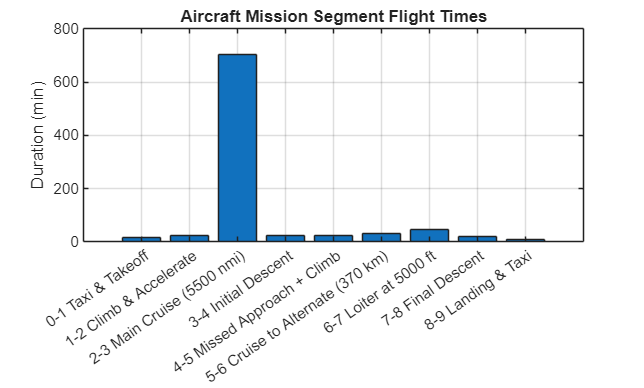


%% 7. Plot segment durations
figure;
bar(time_min);
grid on;
xticks(1:length(segment_names));
xticklabels(segment_names);
xtickangle(35);
ylabel('Duration (min)');
title('Aircraft Mission Segment Flight Times');

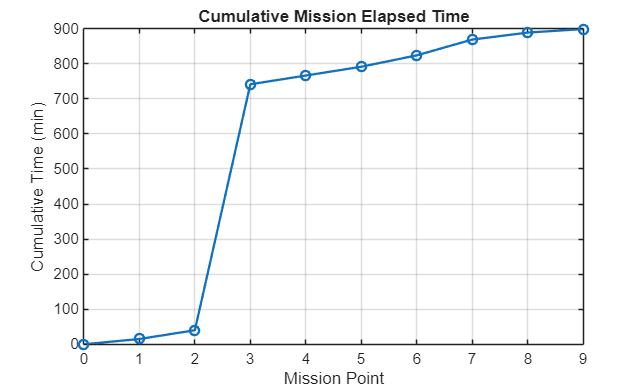


%% 8. Plot cumulative mission time
figure;
plot(0:9, [0; cumulative_min], '-o', 'LineWidth', 1.5);
grid on;
xlabel('Mission Point');
ylabel('Cumulative Time (min)');
title('Cumulative Mission Elapsed Time');
xlim([0 9]);